# Reference

[1] Le Kien, Fam, Philipp Schneeweiss, and Arno Rauschenbeutel. "Dynamical polarizability of atoms in arbitrary light fields: general theory and application to cesium." *The European Physical Journal D* 67.5 (2013): 1-16.

# AC Stark interaction

For far-off-resonance light $\mathbf{E}=\frac{1}{2}E\mathbf{u}e^{i\omega t}+c.c.$coupling state $|a\rangle$ and $|b\rangle$


$$\delta E_a =-\frac{|E|^2}{4\hbar}\sum_{b}\mathrm{Re}\left(
\frac{|\langle b|\mathbf{u\cdot d}|a\rangle|^2}{\omega_b-\omega_a-\omega-i\gamma_{ba}/2})+
\frac{|\langle a|\mathbf{u\cdot d}|b\rangle|^2}{\omega_b-\omega_a+\omega+i\gamma_{ba}/2}\right)$$


# Polarizability of Cs atoms

Stark interaction operator


$$V_{EE} = -\frac{1}{4}|E|^2
\left\{\alpha_{nJ} ^{s}-
i\alpha_{nJ}^{v}\frac{[\mathbf{u}^*\times\mathbf{u}]\cdot\mathbf{J}}{2J}+
\alpha_{nJ}^T\frac{3[(\mathbf{u^*}\cdot\mathbf{J})(\mathbf{u}\cdot\mathbf{J})
+(\mathbf{u}\cdot\mathbf{J})(\mathbf{u^*}\cdot\mathbf{J})]
-2\mathbf{J}^2}{2J(2J-1)}\right\}$$


where


$$\alpha_{nJ}^s = \frac{1}{\sqrt{3(2J+1)}} \alpha_{nJ}^{(0)}$$



$$\alpha_{nJ}^v = -\sqrt{\frac{2J}{(J+1)(2J+1)}}\alpha_{nJ}^{(1)}$$



$$\alpha_{nJ}^T=-\sqrt{\frac{2J(2J-1)}{3(J+1)(2J+1)(2J+3)}}\alpha_{nJ}^{(2)}$$


and


$$\alpha_{nJ}^{(K)}=(-1)^{(K+J+1)}\sqrt{2K+1}\\
\times\sum_{n\prime J\prime}(-1)^{J\prime}
\left\{\begin{array}{c c c} 
   1 & K & 1\\ 
   J & J\prime & J
\end{array}\right\}
|\langle n\prime J\prime\|\mathbf{d}\|nJ\rangle|^2\\
\times \frac{1}{\hbar}\mathrm{Re}\left(
\frac{1}{\omega_{n\prime J\prime nJ}-\omega-i\gamma_{n\prime J\prime nJ}/2}+
\frac{(-1)^K}{\omega_{n\prime J\prime nJ}+\omega+i\gamma_{n\prime J\prime nJ}/2}
\right)$$


# Magic wavelength

Magic wavelength is the wavelength where the static polarizability of ground state is the same as of excited state.

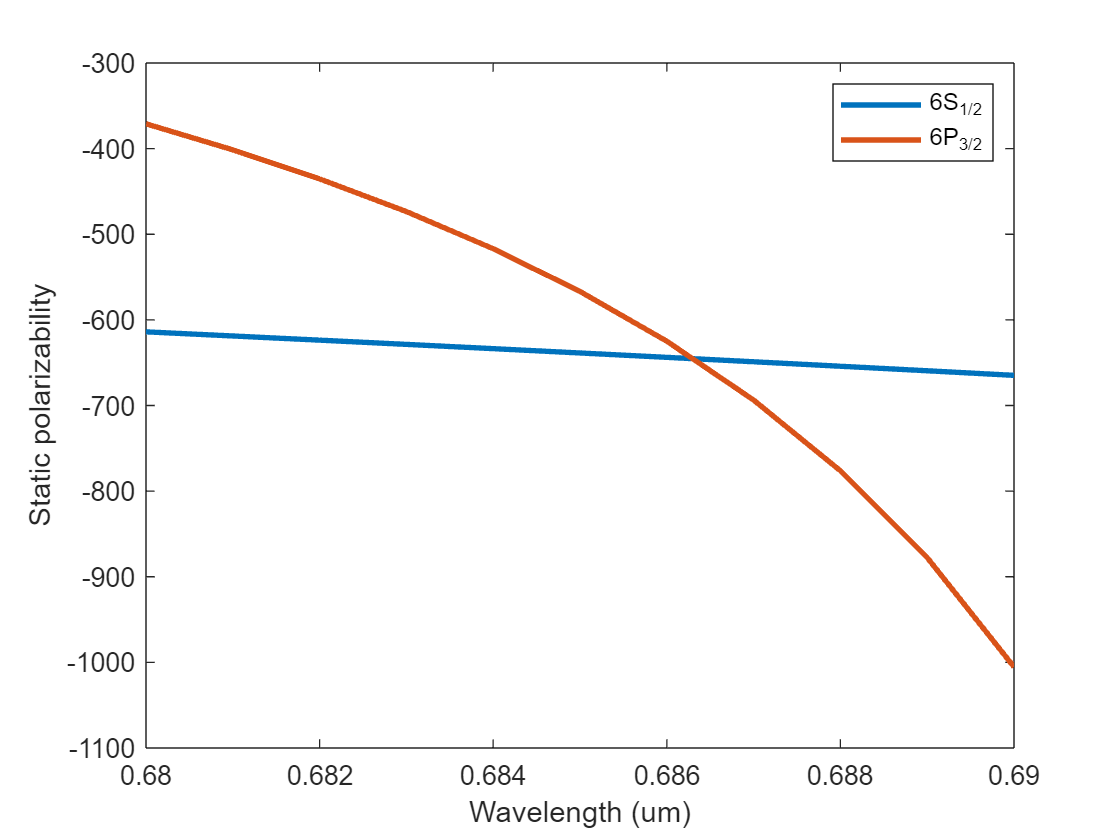

clear
clc

alphaSs = @(x) aNLJ('s',6,0,1/2,x,'AU');
alphaPs = @(x) aNLJ('s',6,1,3/2,x,'AU');

Wavelength = 0.68:0.001:0.69;
plot(Wavelength,alphaSs(Wavelength),Wavelength,alphaPs(Wavelength),'LineWidth',2)
xlabel('Wavelength (um)')
ylabel('Static polarizability')
legend({'6S_{1/2}','6P_{3/2}'})

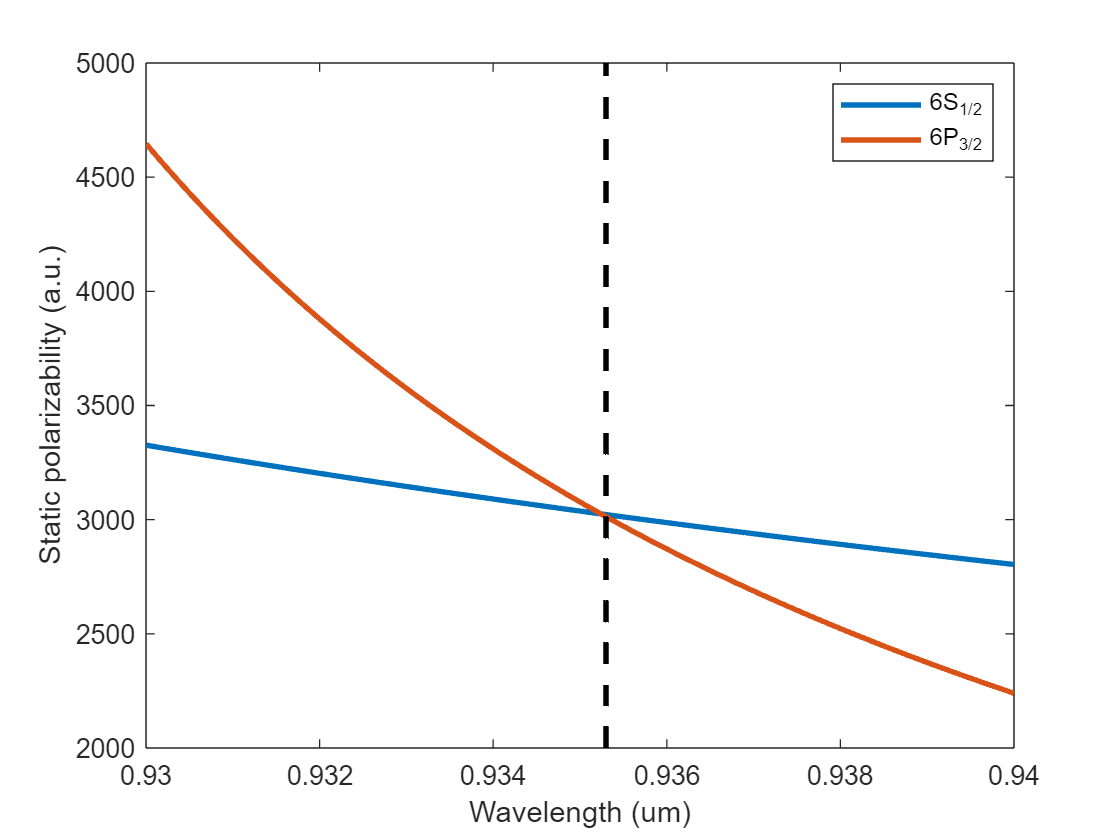

Wavelength = 0.93:0.0001:0.94;
plot(Wavelength,alphaSs(Wavelength),Wavelength,alphaPs(Wavelength),'LineWidth',2)
hold on
line([0.9353,0.9353],ylim,'LineStyle','--','Color','k','LineWidth',2)
hold off
xlabel('Wavelength (um)')
ylabel('Static polarizability (a.u.)')
legend({'6S_{1/2}','6P_{3/2}'})

# Tune-out wavelength

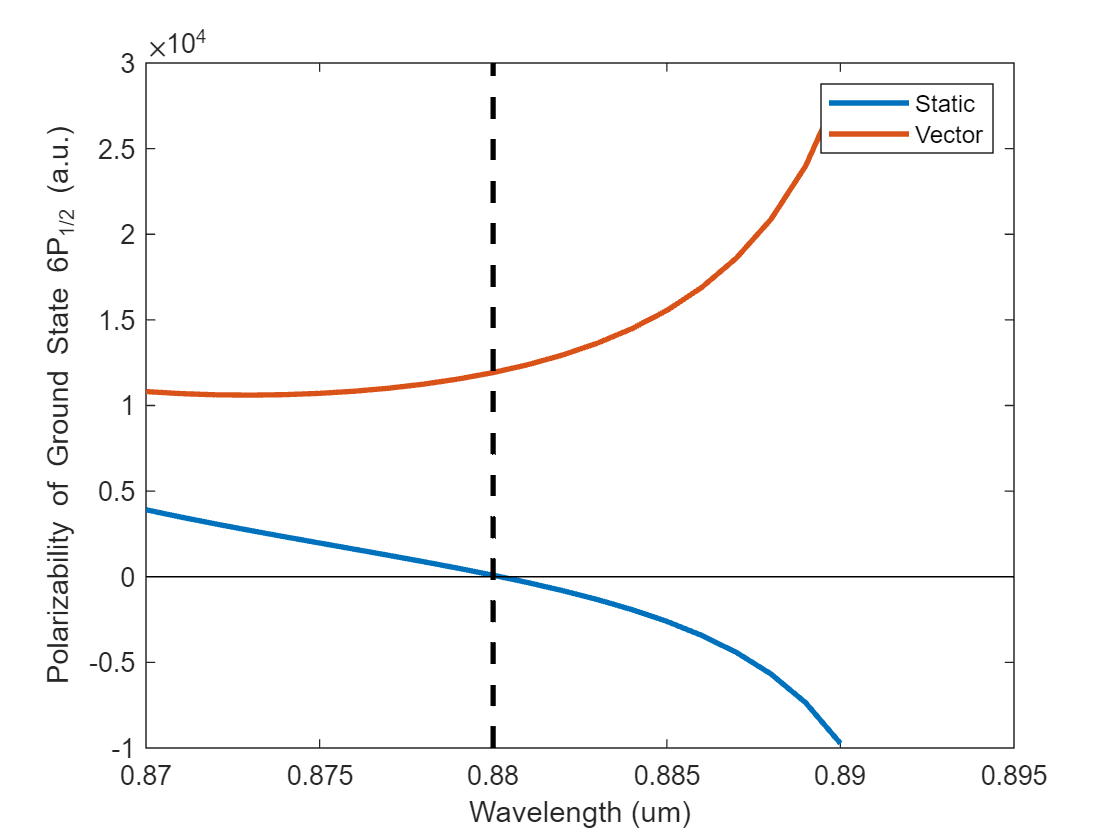

alphaSv = @(x) aNLJ('v',6,0,1/2,x,'AU');

Wavelength = 0.87:0.001:0.89;
plot(Wavelength,alphaSs(Wavelength),Wavelength,alphaSv(Wavelength),'LineWidth',2)
axis manual
hold on
line([0.88,0.88],ylim,'Color','k','LineStyle','--','LineWidth',2)
line(xlim,[0,0],'Color','k')
hold off
xlabel('Wavelength (um)')
ylabel('Polarizability of Ground State 6P_{1/2} (a.u.)')
legend({'Static','Vector'})

When the Stark interaction is small compared to hyperfine splitting, the mixing between different F states can be neglected. The Stark operator can be presented in this form


$$V_{EE} = -\frac{1}{4}|E|^2
\left\{\alpha_{nJF} ^{s}-
i\alpha_{nJF}^{v}\frac{[\mathbf{u}^*\times\mathbf{u}]\cdot\mathbf{F}}{2F}+
\alpha_{nJF}^T\frac{3[(\mathbf{u^*}\cdot\mathbf{F})(\mathbf{u}\cdot\mathbf{F})
+(\mathbf{u}\cdot\mathbf{F})(\mathbf{u^*}\cdot\mathbf{F})]
-2\mathbf{F}^2}{2F(2F-1)}\right\}$$


where


$$\alpha_{nJF}^s = \alpha_{nJ}^s=\frac{1}{\sqrt{3(2J+1)}} \alpha_{nJ}^{(0)}$$



$$\alpha_{nJF}^v = (-1)^{J+I+F}\sqrt{\frac{2F(2F+1)}{F+1}}
\Bigg\{\begin{array}{ccc}
F & 1 & F\\
J & I & J
\end{array}\Bigg\}
\alpha_{nJ}^{(1)}$$



$$\alpha_{nJ}^T=-(-1)^{J+I+F}\sqrt{\frac{2F(2F-1)(2F+1)}{3(F+1)(2F+3)}}
\Bigg\{\begin{array}{ccc}
F & 2 & F\\
J & I & J
\end{array}\Bigg\}
\alpha_{nJ}^{(2)}$$


This expression assumes the detuning is large compared to hyperfine splitting.

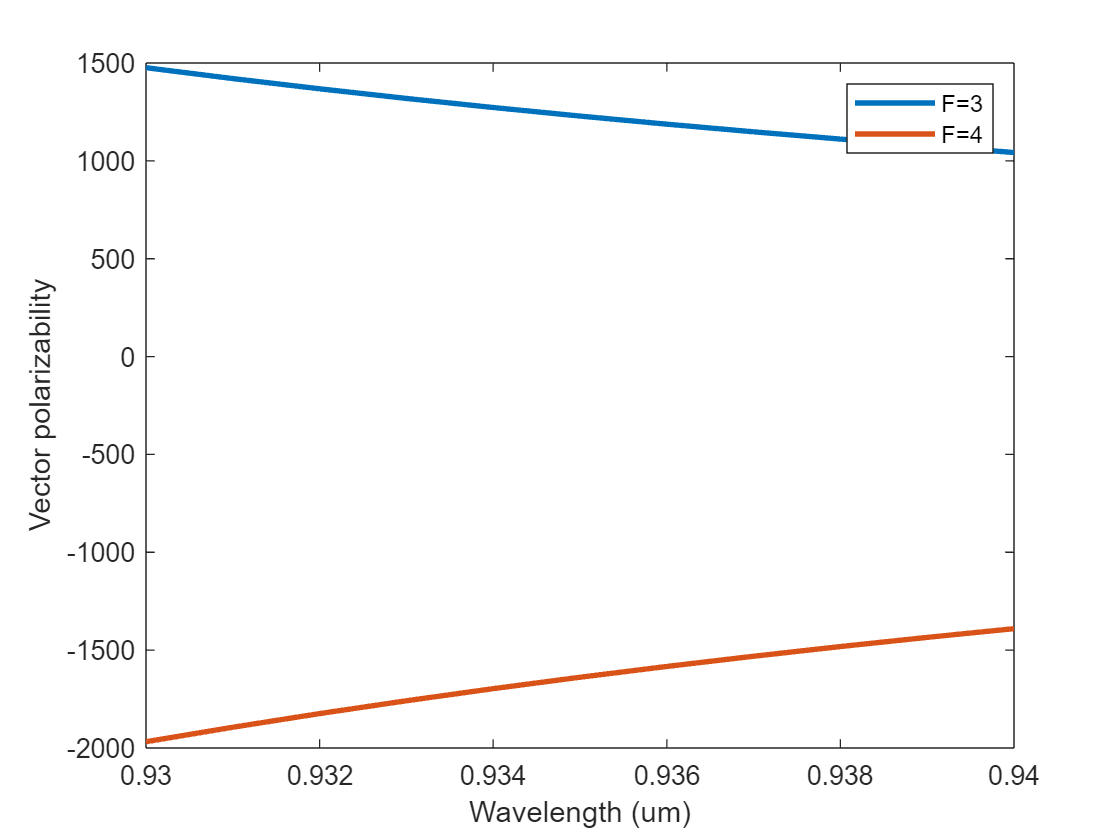

alphaSv3 = @(x) aNLJF('v',6,0,1/2,3,x,'AU');
alphaSv4 = @(x) aNLJF('v',6,0,1/2,4,x,'AU');
Wavelength = 0.93:0.001:0.94;
plot(Wavelength,alphaSv3(Wavelength),Wavelength,alphaSv4(Wavelength),"LineWidth",2)
xlabel('Wavelength (um)')
ylabel('Vector polarizability')
legend({'F=3','F=4'})

We can compare the static and vector light shift within a large range of wavelength

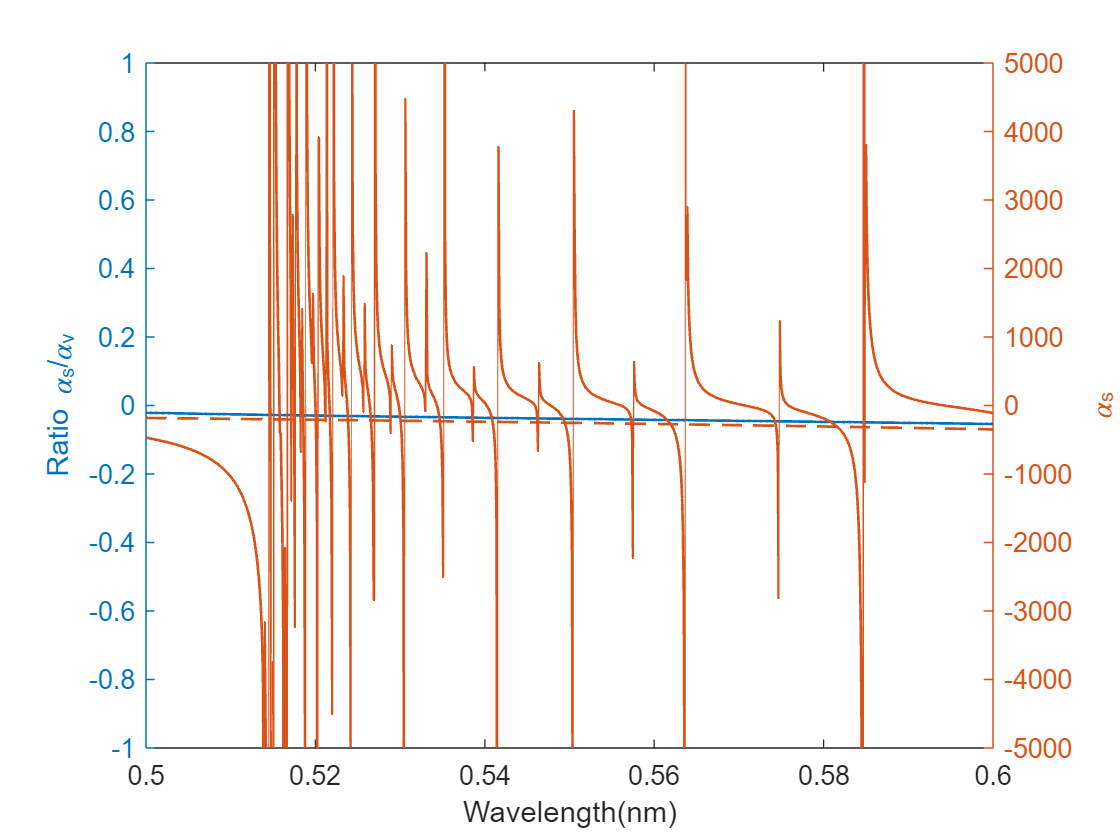

alphaRatio = @(x) alphaSv3(x)./alphaSs(x);

Wavelength = 0.5:0.0001:0.6;
% Wavelength = 0.5:0.0001:0.9;
% Wavelength = 0.9:0.001:0.96;
figure
yyaxis left
plot(Wavelength,alphaRatio(Wavelength),'LineWidth',1)
ylim([-1 1])
ylabel('Ratio \alpha_s/\alpha_v')
yyaxis right
plot(Wavelength,alphaSs(Wavelength),"--","LineWidth",1)
hold on
plot(Wavelength,alphaPs(Wavelength),"-","LineWidth",1)
ylabel('\alpha_s')
ylim([-5e3 5e3])
xlabel('Wavelength(nm)')

If the quantization axis is along z direction (given by an external magnetic field), the ac Stark shift of a Zeeman sublevel $|FM\rangle$can be written as


$$\Delta E_{ac} = \langle FM|V_{EE}|FM\rangle =
-\frac{1}{4}|E|^2
\left[\alpha_{nJF}^s + 
C\alpha_{nJF}^v\frac{M}{2F}-
D\alpha_{nJF}^T\frac{3M^2-F(F+1)}{2F(2F-1)}
\right]$$


where


$$C = |u_{-1}|^2-|u_1|^2=2\mathrm{Im}(u_x^*u_y)$$



$$D = 1-3|u_0|^2 = 1-3|u_z|^2$$


# Fictious magnetic field


$$\mathbf{B}^{fict} = \frac{\alpha_{nJ}^v}{8\mu_Bg_{nJ}J}i[\mathbf{E^*}\times\mathbf{E}]
= \frac{\alpha_{nJF}^v}{8\mu_Bg_{nJF}F}i[\mathbf{E^*}\times\mathbf{E}]$$


Non-relativistic value of g-factor is


$$g_{nJ} = g_L\frac{J(J+1)+L(L+1)-S(S+1)}{2J(J+1)}+g_S\frac{J(J+1)+S(S+1)-L(L+1)}{2J(J+1)}$$


Here $g_L = 1, g_S \simeq 2.0023193$.


$$g_{nJF} = g_{nJ}\frac{F(F+1)+J(J+1)-I(I+1)}{2F(F+1)}$$
